line_list_1 = importdata('LINE_LIST_1.DAT');
line_list_2 = importdata('LINE_LIST_2.DAT');
point_list_1 = importdata('POINT_LIST_1.DAT');
point_list_2 = importdata('POINT_LIST_2.DAT');

% create edges
line_list = line_list_1;
point_list= point_list_1;
line = [line_list(1,2)];
for n = 2: length(line_list(:,1))
    index = find(line_list(:,2) == line(end));
    line(n) = line_list(index,3);
end 
% size(line)
% line(end+1) = line_list(1,2);
% size(line)

line = line';

point_list= point_list_1;
wrapped_line = [line(end);line;line(1)]

wrapped_line =    457
     1
   233
   117
   349
    59
   291
   175
   407
     2


XY = point_list(line, 2:3)

XY =    -0.4756    0.5012
   -0.4849    0.4988
   -0.4942    0.4965
   -0.5035    0.4942
   -0.5128    0.4919
   -0.5220    0.4896
   -0.5313    0.4872
   -0.5406    0.4849
   -0.5499    0.4826
   -0.5555    0.4803


wrappedXY = point_list(wrapped_line, 2:3)

wrappedXY =    -0.4698    0.5052
   -0.4756    0.5012
   -0.4849    0.4988
   -0.4942    0.4965
   -0.5035    0.4942
   -0.5128    0.4919
   -0.5220    0.4896
   -0.5313    0.4872
   -0.5406    0.4849
   -0.5499    0.4826


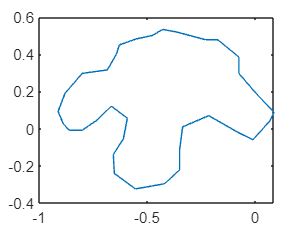

figure(1), clf
plot(wrappedXY(:,1), wrappedXY(:,2))

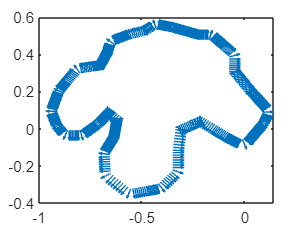


deltaXY = wrappedXY(3:end,:) - wrappedXY(1:end-2,:);
n_v = deltaXY ./ sqrt(deltaXY(:,1).^2 + deltaXY(:,2).^2) ;
n_v = [n_v(:,2), -n_v(:,1)];
quiver(XY(:,1), XY(:,2), n_v(:,1), n_v(:,2))